V = V1+V2+V3, ybar动态更新，保证下一事件开始的V始终小于当前事件初始时刻的V

移动平均法 moving average

clear all;
% case1-1: fixed topology, connected followers
A = [1 1; 0 1];
B = [0; 1];
D1 = diag([2.5 0 1 0 0 1 0 0 0 2]);
W1 = [0 1 2 0 0 0 0 0 0 0;
    1 0 0 1.5 0 0 0 0 0 0;
    2 0 0 0 0.5 0 0 0 0 0;
    0 1.5 0 0 0 0 0 0 0 0;
    0 0 0.5 0 0 0 0 0 2 0;
    0 0 0 0 0 0 1 3 0 0;
    0 0 0 0 0 1 0 0 1.5 0;
    0 0 0 0 0 3 0 0 0 1;
    0 0 0 0 2 0 1.5 0 0 0;
    0 0 0 0 0 0 0 1 0 0];
L1 = -W1 + diag(sum(W1, 2));  % Laplacien matrix
H1 = L1+D1;

P = [23 9.5; 9.5 8];
%P = [21.5 9; 9 7.5];
%P = P1;
K = B'*P;


% parameters
delta_min = min(eig(H1));
alpha = abs(max( eig((P*A+A'*P)/2) ) );
epsilon = abs(max( eig((A+A')/2) ) );
beta = max(eig(P*B*B'*P));
delta = max(eig(H1));
eta = min(eig(P));
eta_max = max(eig(P));
tau = 1;
y_bar_initial = 1000;
y_bar = y_bar_initial*ones(10,1);

% leader
x0_initial = [1;1];
y_initial = y_bar;

% followers
x_initial =  zeros(20,1);
for i=1:10
    x_initial(2*i-1: 2*i) = [0.5*i+10; i+2.5];
end

% buffer
t_span =40; % 仿真时长
t_step = 0.001;
nb_t =floor(t_span/t_step)+1;

t_history = zeros(1,nb_t);
V_history = zeros(1,nb_t);
V1_history = zeros(1,nb_t);
V2_history = zeros(1,nb_t);
V3_history = zeros(1,nb_t);
x_history = zeros(20,nb_t);
xi_history = zeros(20,nb_t);
e_history = zeros(20,nb_t);
x0_history = [];
y_history = zeros(10,nb_t);
z_history = [];
u_hisroty = [];
x = x_initial;
x0 = x0_initial;
x_hat = x_initial;
% z = zeros(10,1);
y = y_initial;

xi_initial = x_initial - kron(ones(10,1), x0_initial);
xi = xi_initial;
e_initial = kron(ones(10,1), [0;0]);
e = e_initial;
z_initial = -kron(H1, eye(2))*(e_initial+xi_initial);
XX = [xi_initial; e_initial; z_initial]; % xi:1-20, e:21-40, z:41-60
XX_history = zeros(60,nb_t);
% dot_XX = AA*XX
% XX(k+1) = XX + AA*XX*t_step
AA = [kron(eye(10),A)-kron(H1,B*K) -kron(H1, B*K) zeros(20);
    zeros(20) kron(eye(10),A) -kron(eye(10),B*K);
    zeros(20) zeros(20) kron(eye(10),A) ];
AAA = [kron(eye(10),A)-kron(H1,B*K) -kron(H1, B*K);
    kron(H1,B*K) kron(eye(10),A)+kron(H1,B*K)];
z = -kron(H1, eye(2))*(e+xi);

V_last = zeros(10,1);
t_last = zeros(10,1);
V1_last = zeros(10,1);
t1_last = zeros(10,1);

for k = 1:10 % initialize V_last and V1_last
    zi = z(2*i-1 : 2*i);
    xii = xi(2*i-1 : 2*i);
    V_last(k) = xii'*P*xii + zi'*zi*y(i);
    V1_last(k) = xii'*P*xii;
end

y_bar_history = zeros(10,nb_t);
y_bar_history(:,1) = y_bar;
V_each_history = zeros(10,nb_t);
times_trigger = zeros(10,1);

% V历史l步记录
l = 3;
z_initial = -kron(H1, eye(2))*(e_initial+xi_initial);
V_line_previous = zeros(10,l);
for i = 1:10
zi = z(2*i-1 : 2*i);
xii = xi(2*i-1 : 2*i);
V_line_previous(i,:) = ones(1,l)*(xii'*P*xii + zi'*zi*y_initial(i));
end


% simulation begins
ite = 0;
adaptive = 1;
for t = 0:t_step:t_span
    ite = ite + 1;

    xi_history(:,ite) = xi;
    e_history(:,ite) = e;
    t_history(:,ite) = t;
    V1 = xi'*kron(eye(10), P)*xi;
    V2 = e'*kron(diag(y),eye(2))*kron(eye(10),P)*e;
    V3 = z'*kron(diag(y),eye(2))*z;
    V = V1 + V2 + V3;
    V_history(ite) = V;
    V1_history(ite) = V1;
    V2_history(ite) = V2;
    V3_history(ite) = V3;

    for i = 1:10
        ei = e(2*i-1 : 2*i);
        zi = z(2*i-1 : 2*i);
        xii = xi(2*i-1 : 2*i);
        V_each_history(i,ite) = xii'*P*xii + ei'*y(i)*P*ei + zi'*y(i)*zi;
    end

    % trigger_index = [];
    z = -kron(H1, eye(2))*(e+xi);
    for i = 1:10
        ei = e(2*i-1 : 2*i);
        zi = z(2*i-1 : 2*i);
        if norm(ei) ~=0 || norm(zi) ~= 0
            gamma = -(2*alpha*y(i)+2*delta*beta + (y(i)-1)^2)*(ei')*ei / (eta*(ei')*ei+zi'*zi) ...
                - (2*epsilon*y(i)+beta^2)*(zi')*zi / (eta*(ei')*ei+zi'*zi);
            dydt = gamma -tau;
        else
            dydt = -tau;
        end
        y(i) = y(i) + dydt*t_step;

        
    
    
    end

    

    % update data
    xi_e = [xi; e] + AAA*[xi; e]*t_step;
    xi = xi_e(1:20);
    e = xi_e(21:40);

    

    for i = 1:10
    if y(i) <= 0
        
        
        e(2*i-1 : 2*i) = [0;0];

        z = -kron(H1, eye(2))*(e+xi);
        ei = e(2*i-1 : 2*i);
        zi = z(2*i-1 : 2*i);
        xii = xi(2*i-1 : 2*i);

        times_trigger(i) = times_trigger(i) + 1;
        if adaptive == 1
            rho= 0.1;
            y_bar(i) = min([y_bar_initial, (V_line_previous(i,1)*exp(-rho*(t-t_last(i))) - xii'*P*xii)/(zi'*zi)]);
            %y_bar(i) = (V_line_previous(i,1)*exp(-rho*(t-t_last(i))) - xii'*P*xii)/(zi'*zi);
%             y_bar(i) = min([y_bar_initial, (V_last(i)*exp(-0.01*(t-t_last(i))) - xii'*P*xii)/(zi'*zi)]);
            y_bar(i) = max([0,y_bar(i)]);
        end
        y(i) = y_bar(i);
        y_bar_history(i,ite) = y_bar(i);

        % 记下V_last
        V_line_previous(i,:) = [V_line_previous(i, 2:end) xii'*P*xii + zi'*zi*y(i)];
        V1_last(i) = xii'*P*xii;

        t_last(i) = t;
        t1_last(i) = t;
    end
    end


    y_history(:,ite) = y;
    

    
end
% 
% xi_history = XX_history(1:20,:);
% e_history = XX_history(21:40,:);
%u_history = kron(eye(10),K)*XX_history(41:60,:);

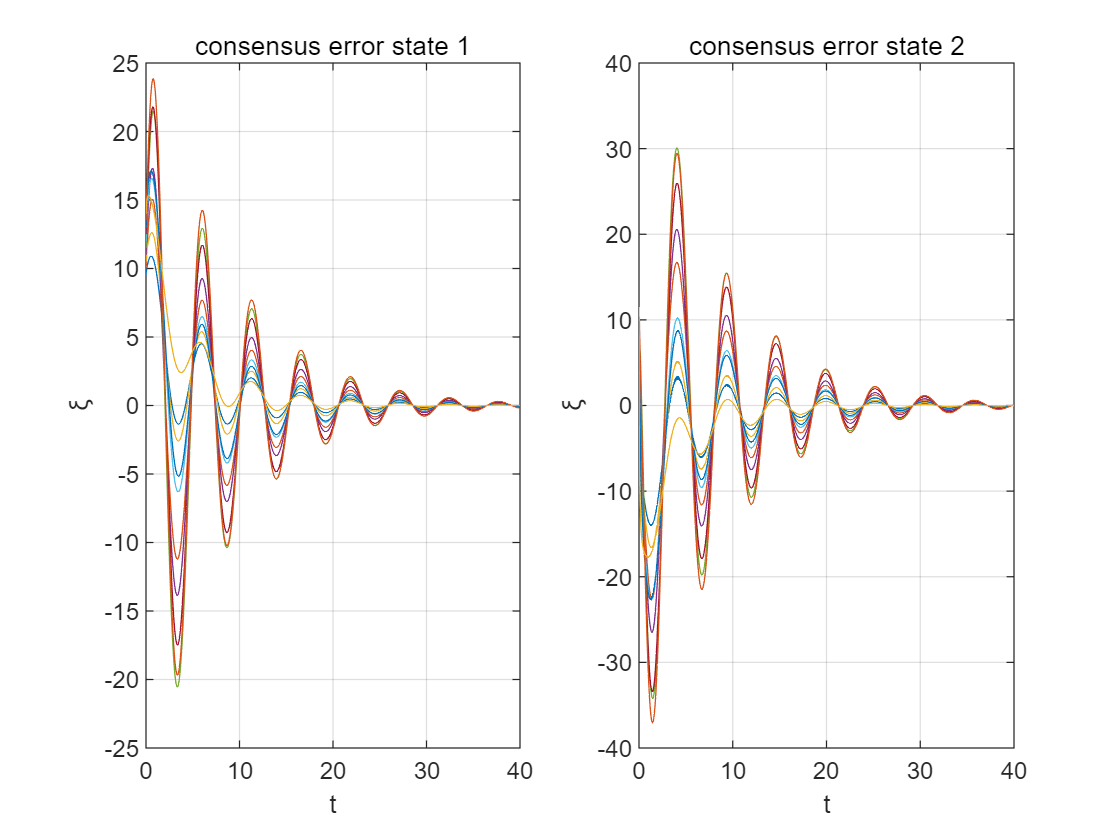


% consensus error
figure()
subplot(1,2,1)
plot(t_history, xi_history(1:2:20,:))
title("consensus error state 1")
xlabel('t')
ylabel('\xi')
grid on

subplot(1,2,2)
plot(t_history, xi_history(2:2:20,:))
title("consensus error state 2")
xlabel('t')
ylabel('\xi')
grid on

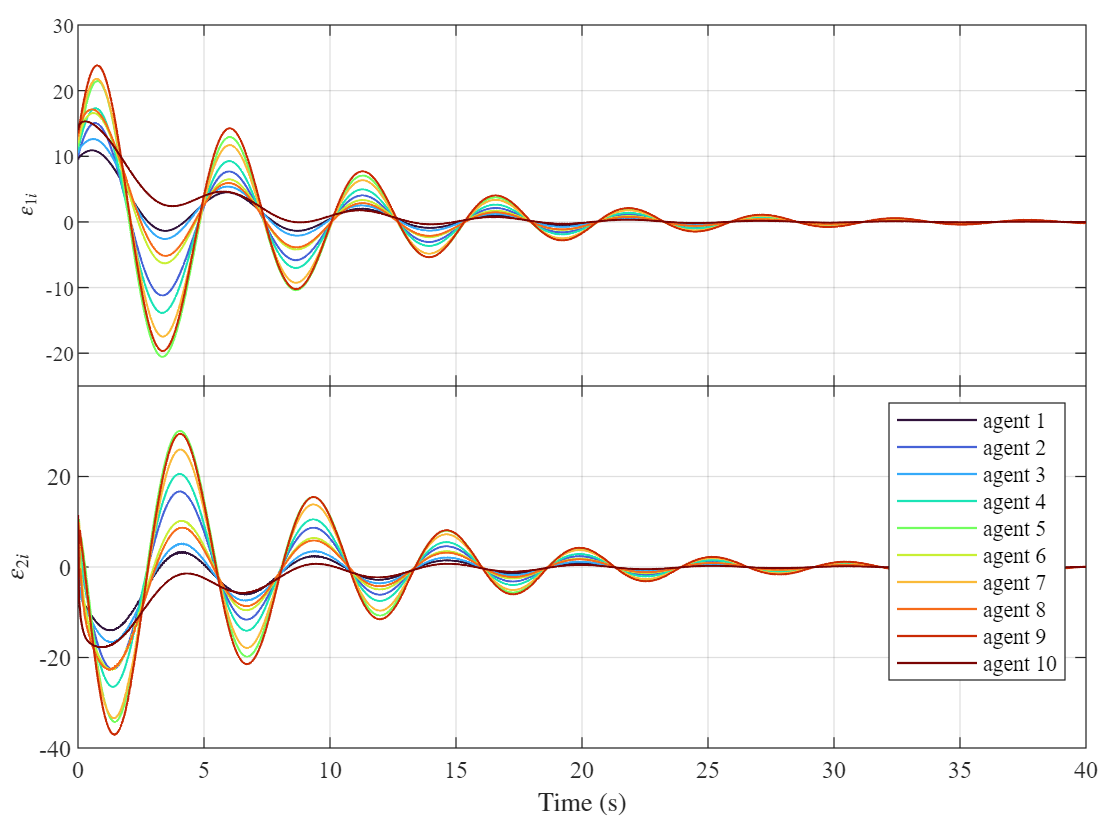

figure()
ywidth = 0.43;
cmap = turbo(10);
subplot(2,1,1)
for i = 1:10
plot(t_history, xi_history(2*i-1,:),"Color",cmap(i,:),'LineWidth',0.8)
hold on
end
hold off
grid on
set(gca, 'Fontname', 'Times New Roman', 'Fontsize',8)
set(gca,'position',[0.07 0.54 0.9 ywidth])
set(gca,'xticklabel',[]);
set(gca,'ytick',[-20 -10 0 10 20 30]);
ylim([-25 30])
ylabel(' $\varepsilon_{1i}$ ','interpreter','latex')


subplot(2,1,2)
for i = 1:10
plot(t_history, xi_history(2*i,:),"Color",cmap(i,:),'LineWidth',0.8)
hold on
end
hold off
grid on
set(gca, 'Fontname', 'Times New Roman', 'Fontsize',9)
set(gca,'position',[0.07 0.54-ywidth 0.9 ywidth])
set(gca,'ytick',[-40  -20  0  20]);
ylim([-40 40])
xlabel("Time (s)",'interpreter','latex')
ylabel(' $\varepsilon_{2i}$ ','interpreter','latex')
legend('agent 1','agent 2','agent 3','agent 4','agent 5','agent 6','agent 7','agent 8','agent 9','agent 10')

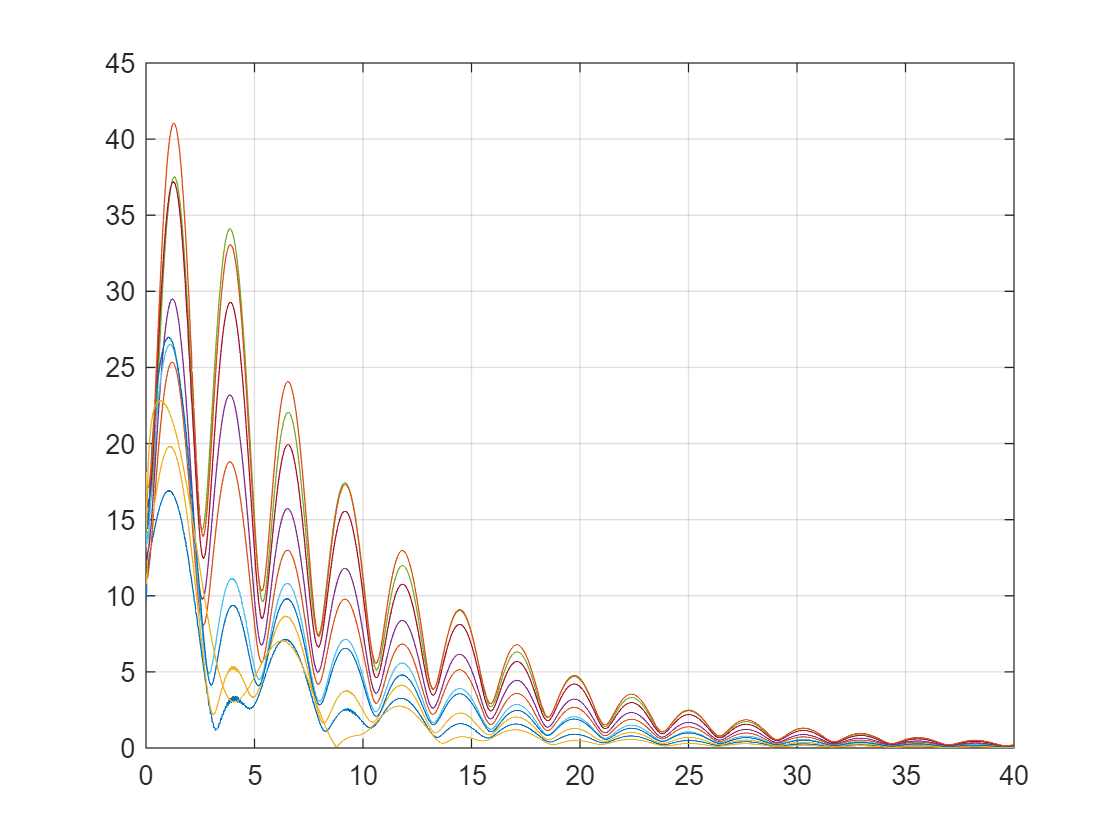


figure()
xi_norm = zeros(10,size(xi_history,2));
for it  = 1:size(xi_norm,2)
    for ia = 1:10
        xi_norm(ia,it) = sqrt(xi_history(2*ia-1,it)^2+xi_history(2*ia,it)^2);
    end
end

plot(t_history, xi_norm)
grid on

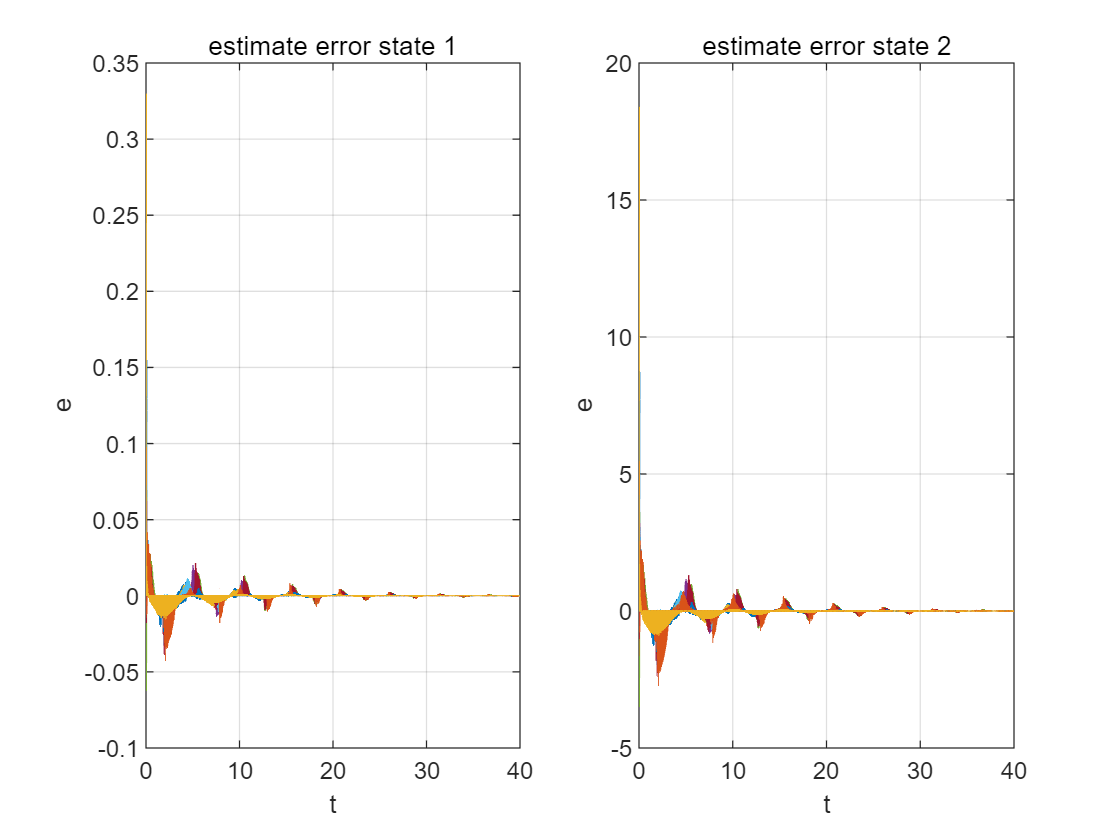


% estimate error
figure()
subplot(1,2,1)
plot(t_history, e_history(1:2:20,:))
title("estimate error state 1")
xlabel('t')
ylabel('e')
grid on

subplot(1,2,2)
plot(t_history, e_history(2:2:20,:))
title("estimate error state 2")
xlabel('t')
ylabel('e')
grid on

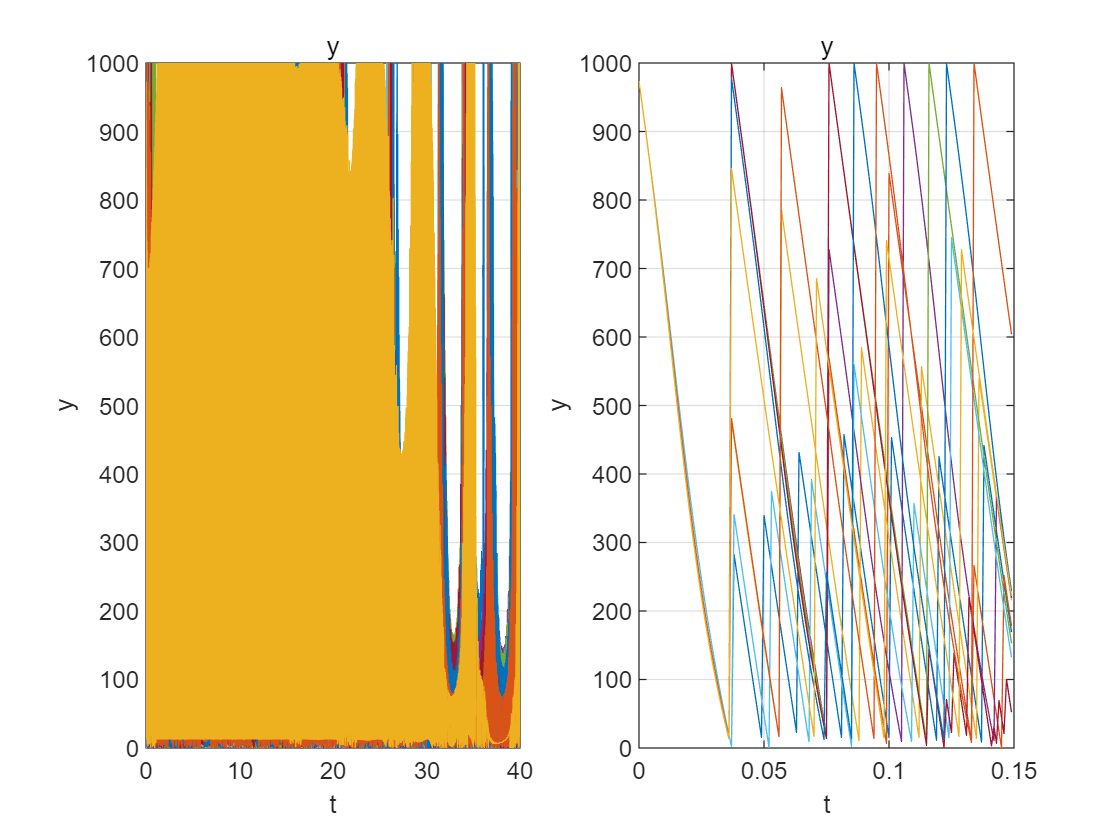


% control input
% figure()
% plot(t_history, u_history(:,:))
% title("control input")
% xlabel('t')
% ylabel('u')
% grid on


figure()
subplot(1,2,1)
plot(t_history, y_history(1:10,:))
xlabel('t')
ylabel('y')
title('y')
grid on;

subplot(1,2,2)
plot(t_history(1:floor(0.15/t_step)), y_history(1:10,1:floor(0.15/t_step)))
xlabel('t')
ylabel('y')
title('y')
grid on;

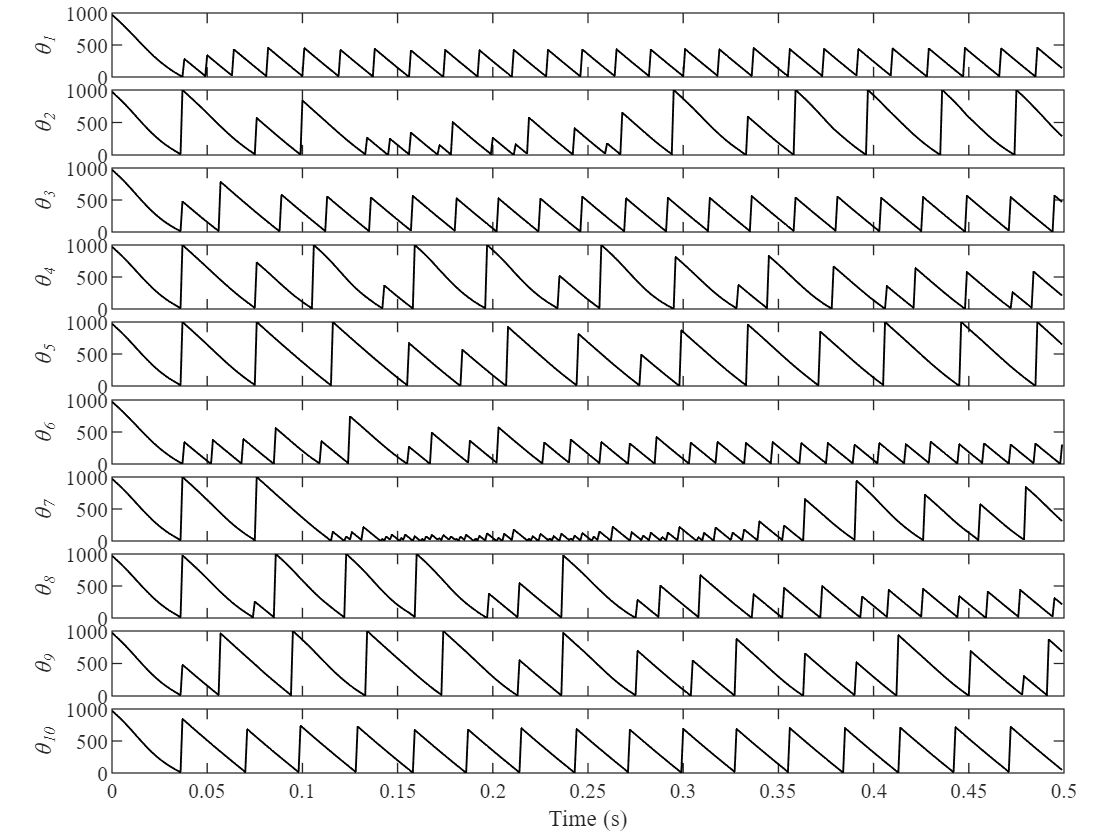


figure()
ywidth = 0.092;
for i = 1:10
subplot(10,1,i)
plot(t_history(1:floor(0.5/t_step)), y_history(i,1:floor(0.5/t_step)),'LineWidth',0.7,'Color','black')
set(gca,'xlim',[0 0.5]);
if i ~= 10
set(gca,'xticklabel',[]);
end
%set(gca,'ytick',[0 500 1000]);
set(gca,'position',[0.1 1-ywidth*i 0.85 ywidth*0.83])
set(gca, 'Fontname', 'Times New Roman', 'Fontsize',8)
ylabel('\it{\theta_{'+string(i)+'}}')
hold on
end
grid off
xlabel("Time (s)")

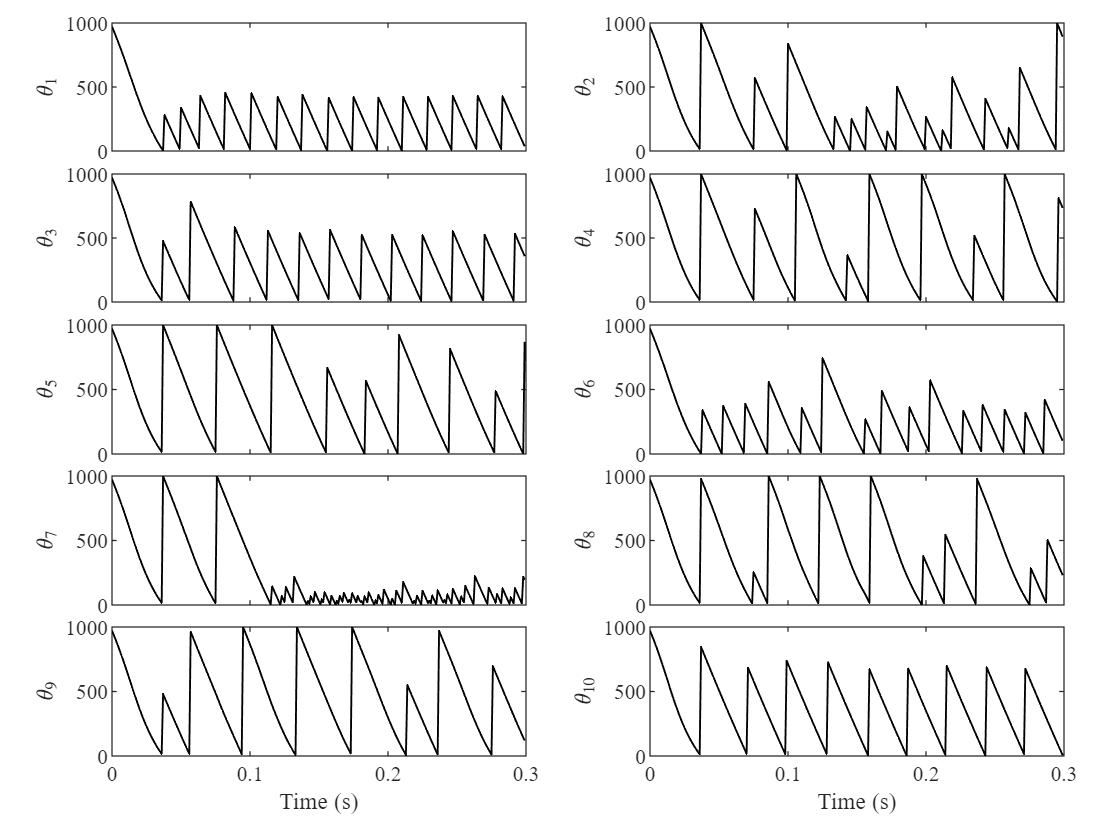

figure()
ywidth = 0.18;
for i = 1:10
subplot(5,2,i)
plot(t_history(1:floor(0.3/t_step)), y_history(i,1:floor(0.3/t_step)),'LineWidth',0.7,'Color','black')
set(gca,'xlim',[0 0.3]);
if i ~= 9 && i ~= 10
set(gca,'xticklabel',[]);
end
%set(gca,'ytick',[0 500 1000]);
%set(gca,'position',[0.1 1-ywidth*i 0.85 ywidth*0.83])
if mod(i,2) == 1
set(gca,'position',[0.1 1-ywidth*(floor((i-1)/2)+1) 0.37 ywidth*0.85])
else
set(gca,'position',[0.58 1-ywidth*(floor((i-1)/2)+1) 0.37 ywidth*0.85])
end
set(gca, 'Fontname', 'Times New Roman', 'Fontsize',8)
ylabel('$\theta_{'+string(i)+'}$','Interpreter','latex')
hold on

if i == 9 || i == 10
xlabel("Time (s)")
end
end

 hold off

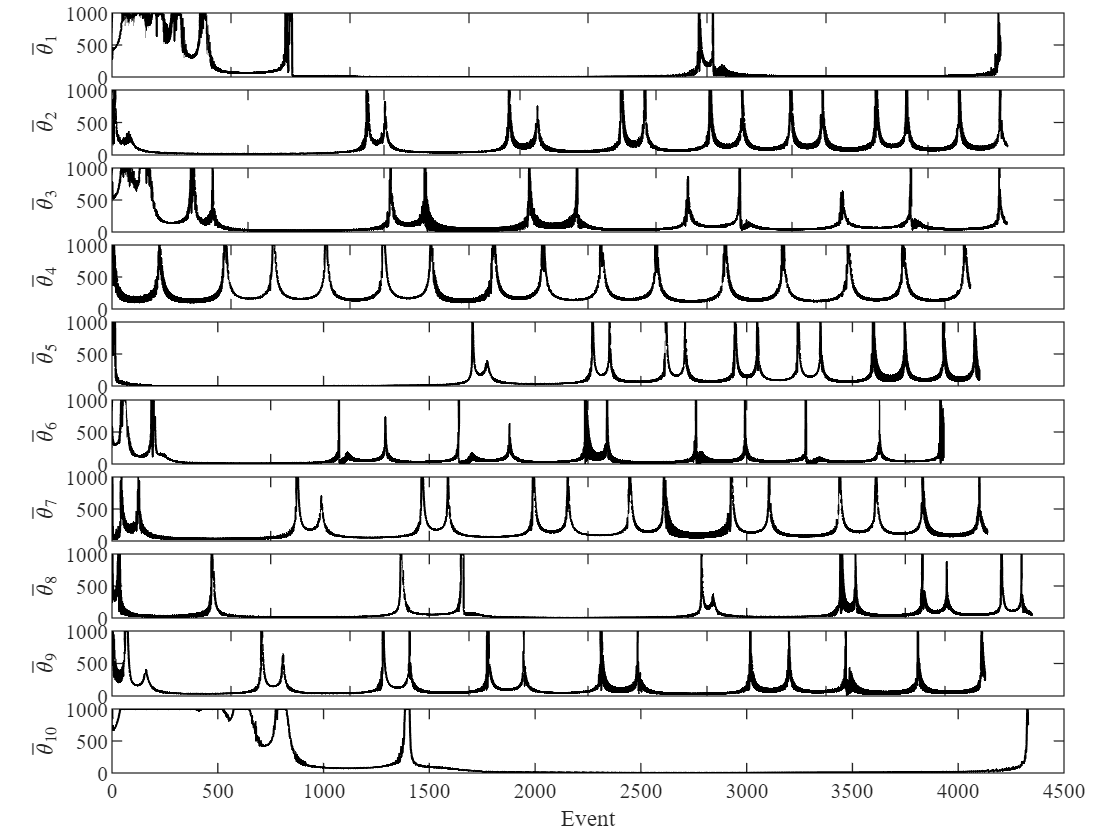


figure()
ywidth = 0.092;
for i = 1:10
subplot(10,1,i)
plot(y_bar_history(i,find(y_bar_history(i,:))),'LineWidth',0.8,'Color','black')
if i ~= 10
set(gca,'xticklabel',[]);
end
set(gca,'position',[0.1 1-ywidth*i 0.85 ywidth*0.83])
set(gca, 'Fontname', 'Times New Roman', 'Fontsize',8)
ylabel('$\bar\theta_{'+string(i)+'}$','Interpreter','latex')
end
xlabel("Event")

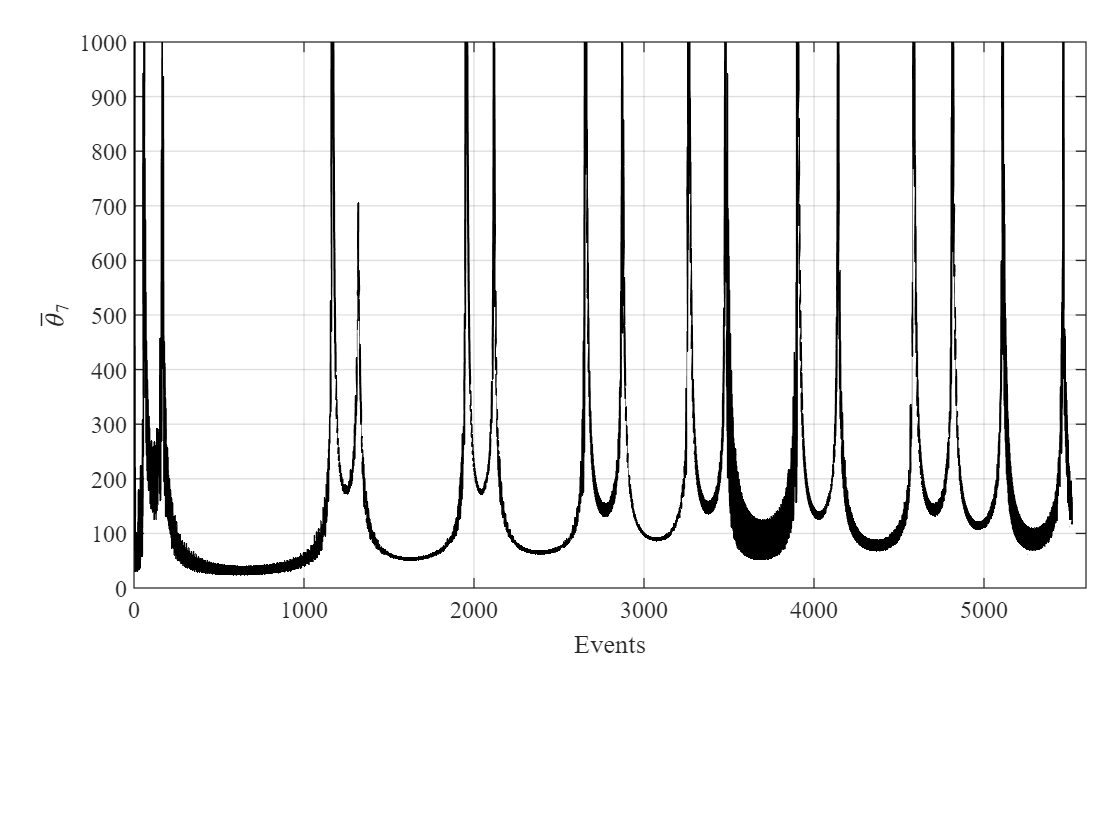

figure()
plot(y_bar_history(7,find(y_bar_history(7,:))),'LineWidth',0.8,'Color','black')
set(gca, 'Fontname', 'Times New Roman', 'Fontsize',9)
set(gca,'position',[0.12 0.3 0.85 0.65])
ylabel('$\bar\theta_{'+string(7)+'}$','Interpreter','latex')
xlabel("Events")
xlim([0 5600])
grid on;



y_bar_non_zero = cell([10 1]);
sum_y_bar = 0;
for i = 1:10
y_bar_non_zero{i} = (y_bar_history(i,find(y_bar_history(i,:))));
sum_y_bar  = sum_y_bar + mean(y_bar_non_zero{i});
end
mean_y_bar = sum_y_bar/10;
disp(mean_y_bar )

  141.3069



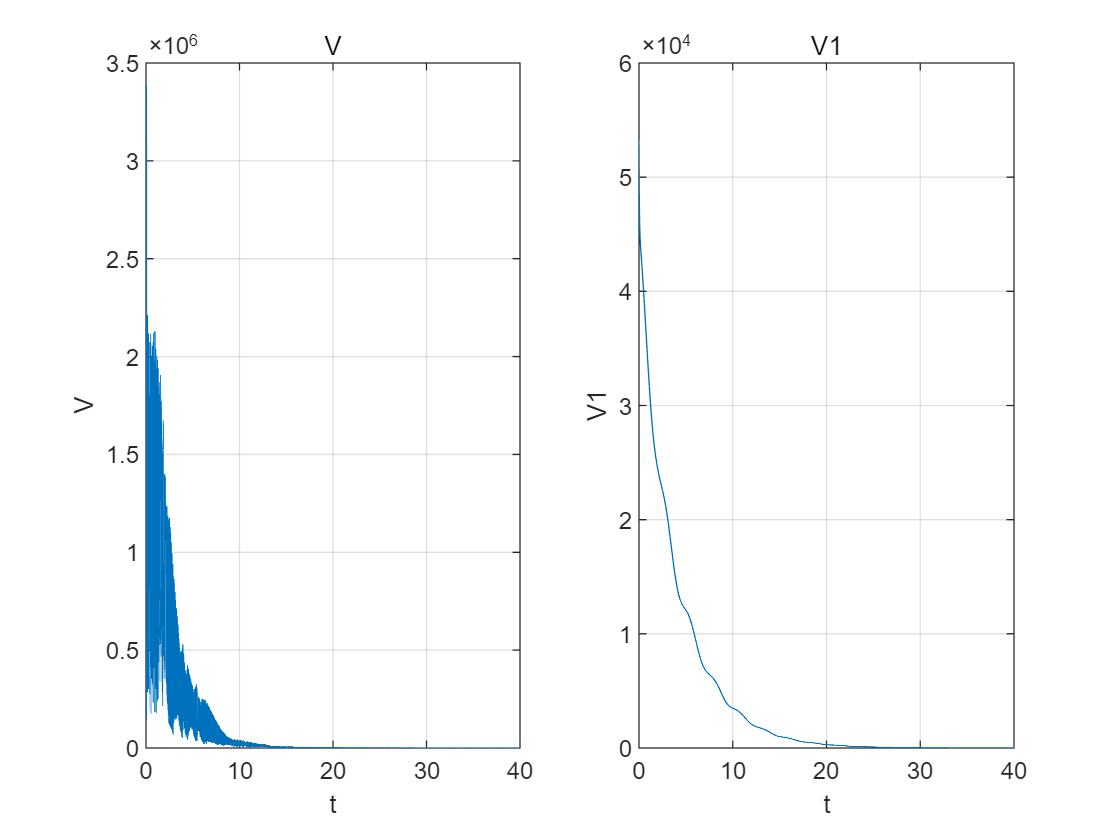




% V
figure()
subplot(1,2,1)
plot(t_history, V_history())
xlabel('t')
ylabel('V')
title('V')
grid on;

subplot(1,2,2)
plot(t_history, V1_history())
xlabel('t')
ylabel('V1')
title('V1')
grid on;

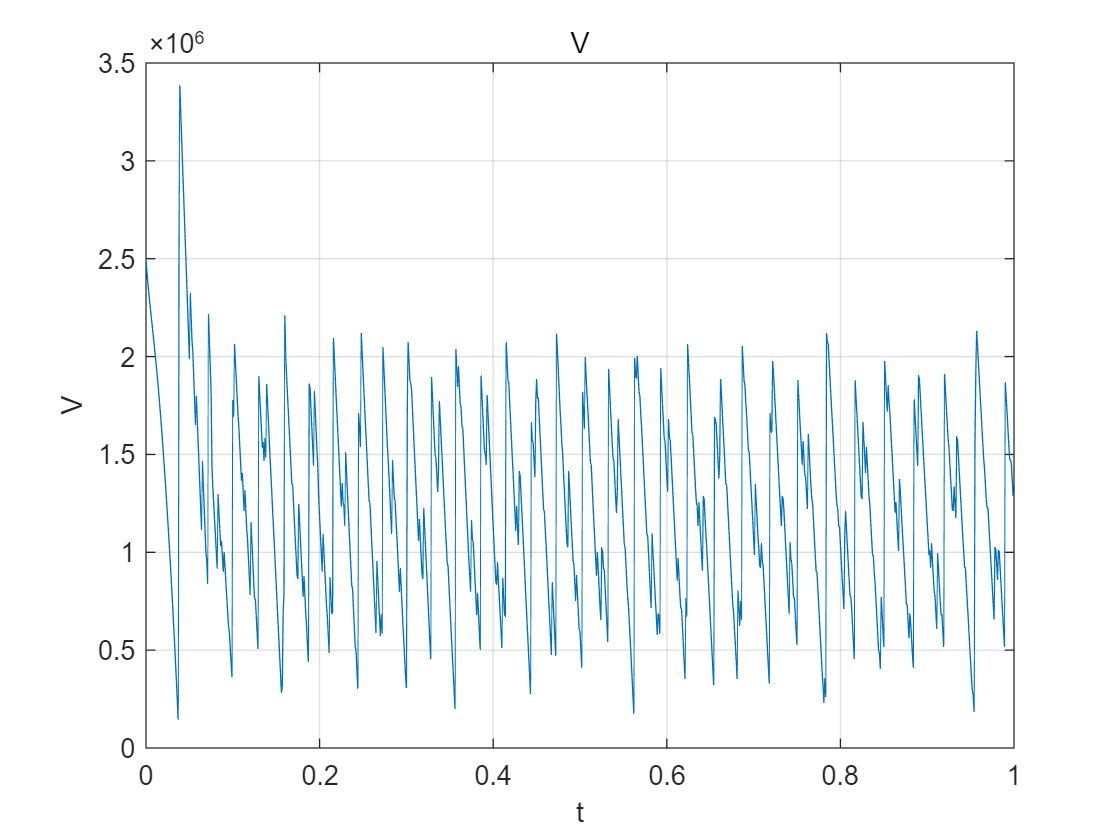

figure()
plot(t_history(1:floor(1/t_step)), V_history(1:floor(1/t_step)))
xlabel('t')
ylabel('V')
title('V')
grid on;

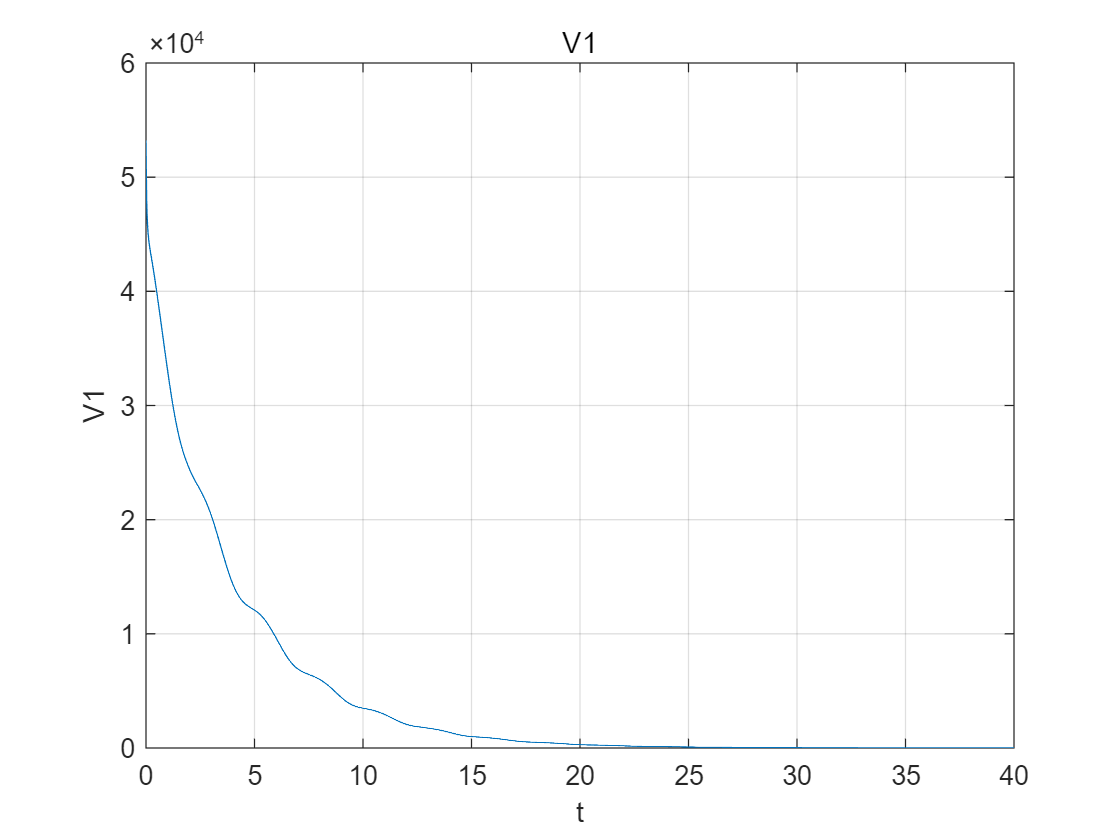

figure()
plot(t_history(1:floor(t_span/t_step)), V1_history(1:floor(t_span/t_step)))
xlabel('t')
ylabel('V1')
title('V1')
grid on;

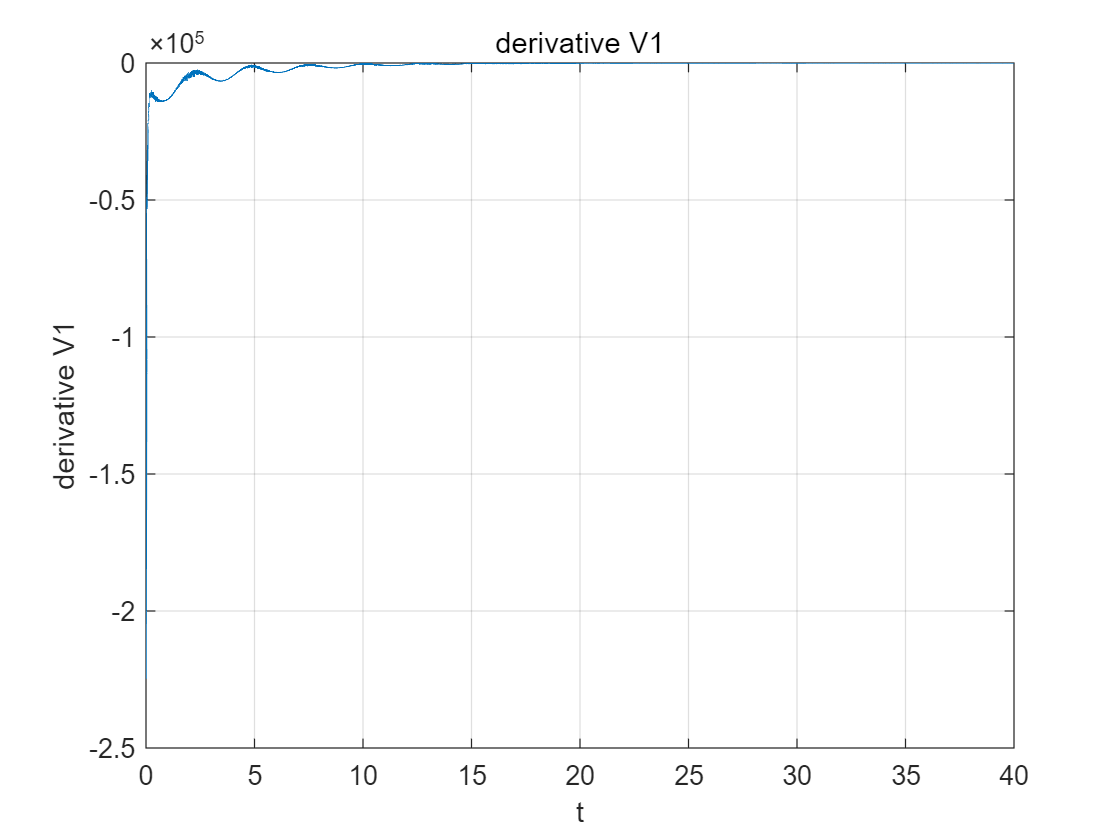

figure()
plot(t_history(2:end), (V1_history(2:end)-V1_history(1:end-1))/t_step)
xlabel('t')
ylabel('derivative V1')
title('derivative V1')
grid on;

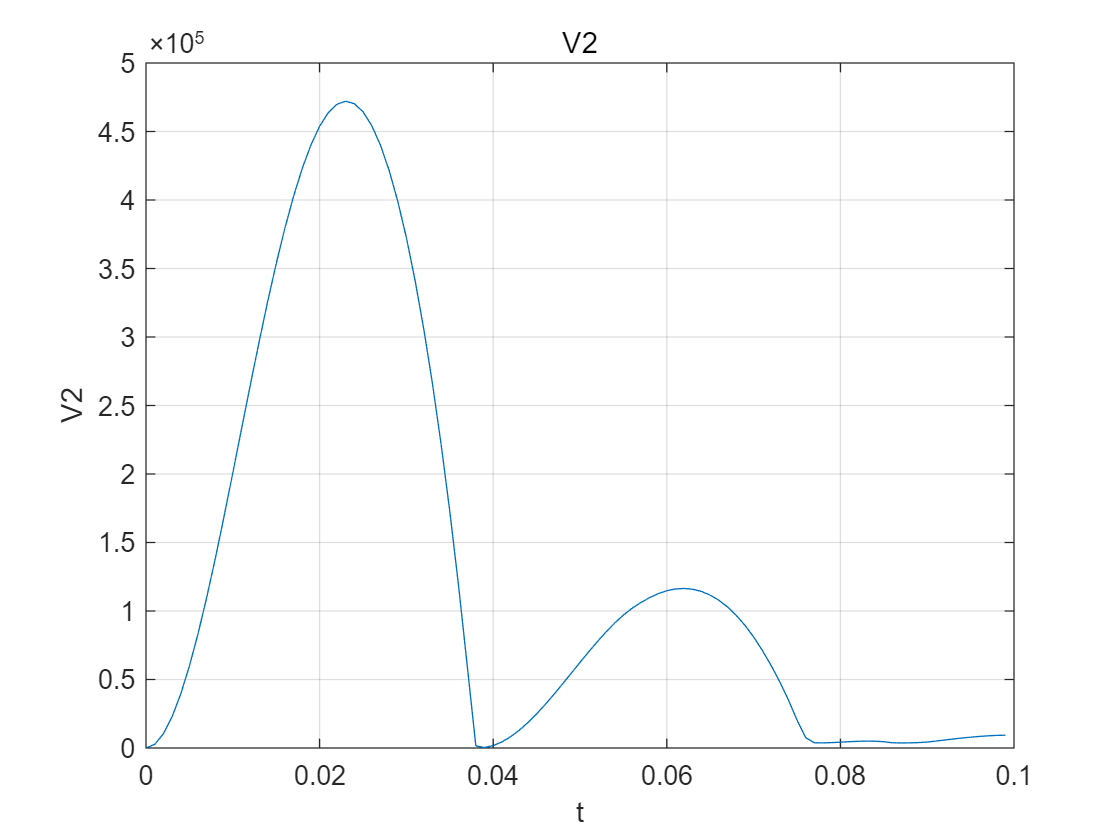


figure()
plot(t_history(1:floor(0.1/t_step)), V2_history(1:floor(0.1/t_step)))
xlabel('t')
ylabel('V2')
title('V2')
grid on;

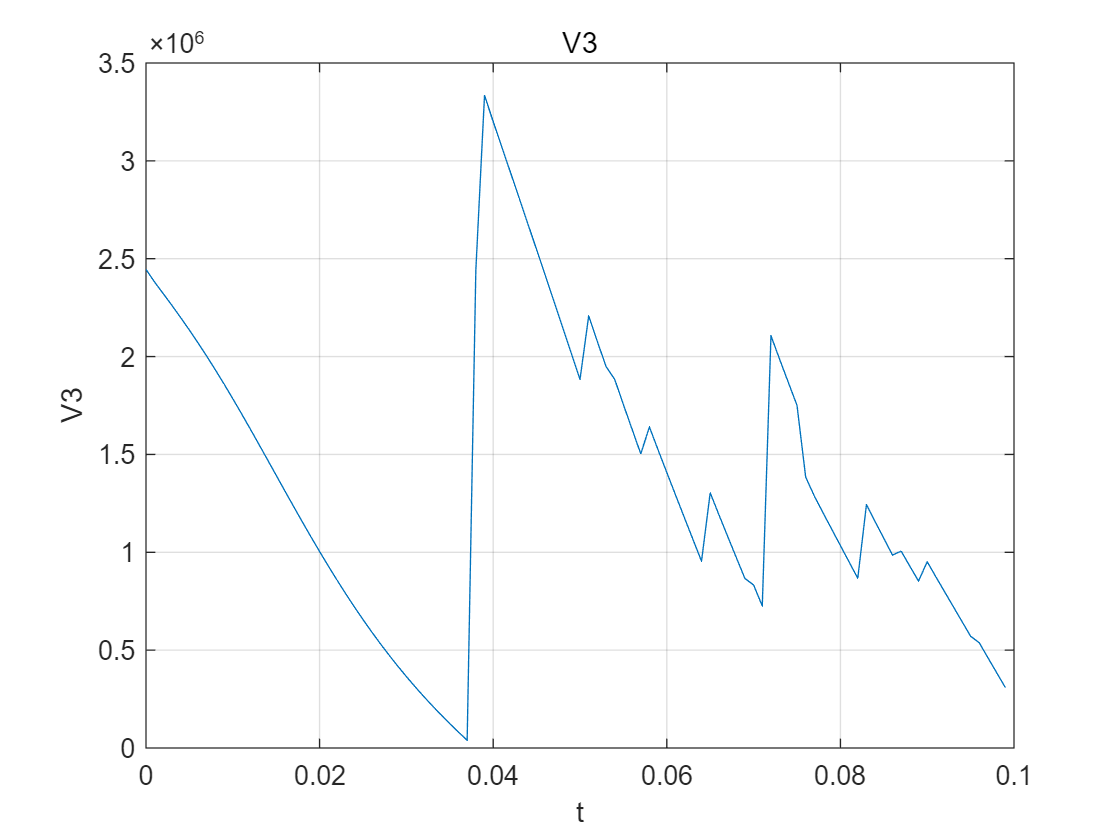

figure()
plot(t_history(1:floor(0.1/t_step)), V3_history(1:floor(0.1/t_step)))
xlabel('t')
ylabel('V3')
title('V3')
grid on;

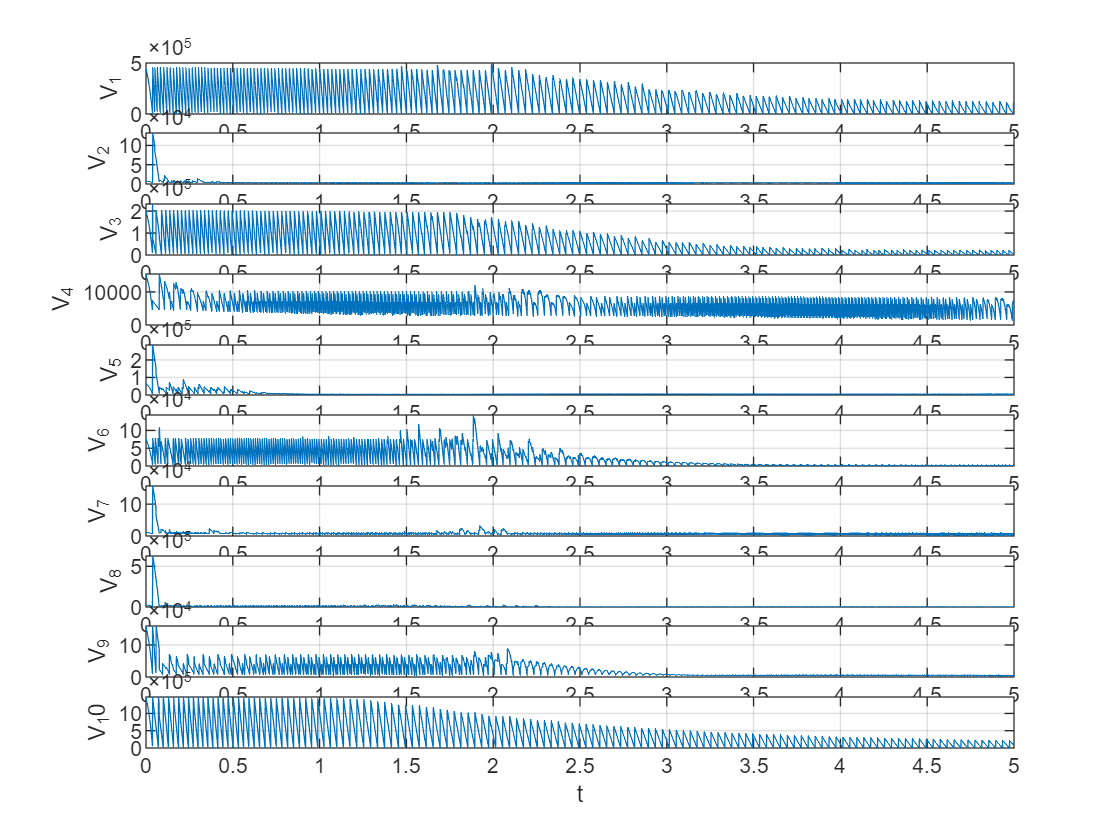

figure()
for i= 1:10
    subplot(10,1,i)
plot(t_history(1:floor(5/t_step)), V_each_history(i,1:floor(5/t_step)))
xlabel('t')
ylabel('V_' + string(i))
grid on;
end

disp(t_span/min(times_trigger)*1000)

   11.0957



disp(t_span/max(times_trigger)*1000)

    3.4492



disp(t_span/mean(times_trigger)*1000)

    5.5596



% figure()
% subplot(4,1,1)
% plot(ybar7_l1_rho01)
% subplot(4,1,2)
% plot(ybar7_l3_rho01)
% subplot(4,1,3)
% plot(ybar7_l10_rho01)
% subplot(4,1,4)
% plot(ybar7_l100_rho01)
